%close all

% Initial Conditions
x0 = [3;  % 3 radians
      0]; % 0 rad/s

% System Dynamics
A = [0    1; 
     0.01 0];
B = [0; 
     1];
C = [1 0];
D = 0;

% Control Law
Q = [1000 0;  % Penalize angular error
     0 1]; % Penalize angular rate
R = 1;     % Penalize thruster effort
K = lqr(A,B,Q,R);

% Closed loop system
sys = ss((A - B*K), B, C, D);

% Run response to initial condition
t = 0:0.005:30;
[y,t,x] = initial(sys, x0, t);


%% Everything below this is just for the visualization

% Patch drawings
ufo_data = [
    0.54 .12;
    0.48 0.24;
    0.42 0.31;
    0.3 0.4;
    0.18 0.45;
    0.06 0.48;
    -0.06 0.48;
    -0.18 0.45;
    -0.3 0.4;
    -0.42 0.31;
    -0.48 0.24;
    -0.54 .12;
    0.54 .12;
    0.54 0.06;
    0.6 0.06;
    0.78 0.03; 
    0.91 0.01;
    0.91 0.03;
    1.01 0.03;
    1.01 -0.01;   
    1.1 -0.03; 
    1.26 -0.12; 
    1.36 -0.18; 
    1.40 -0.21;
    1.38 -0.24;
    1.26 -0.27;
    1.1 -0.3;  
    1.01 -0.32;
    1.01 -0.34;
    0.91 -0.34;
    0.91 -0.32;  
    0.72 -0.34;
    0.48 -0.35;
    0.72 -0.6;
    0.62 -0.6;
    0.38 -0.35;    
    0.3 -0.35;    
    -0.3 -0.35;
    -0.38 -0.35;
    -0.62 -0.6;
    -0.72 -0.6;
    -0.48 -0.35;
    -0.91 -0.32;
    -0.91 -0.34;
    -1.01 -0.34;
    -1.01 -0.32;
    -1.1 -0.3;
    -1.26 -0.27;
    -1.38 -0.24;
    -1.40 -0.21;
    -1.36 -0.18;
    -1.26 -0.12;
    -1.1 -0.03;
    -1.01 -0.01;
    -1.01 0.03;
    -0.91 0.03;
    -0.91 0.01;
    -0.78 0.03;
    -0.6 0.06;
    -0.54 0.06;
    0.54 0.06;
];

thrust = [
    0.05 0;
    -.05 0;
    -.06 -0.1;
    -.05 -0.1;
    -.06 -0.2;
    0 -0.25;
    0.06 -0.2;
    0.05 -0.1;
    0.06 -0.1;
    0.05 0];

% yoffset moves the patch up from 0, 0
yoffset = 1;

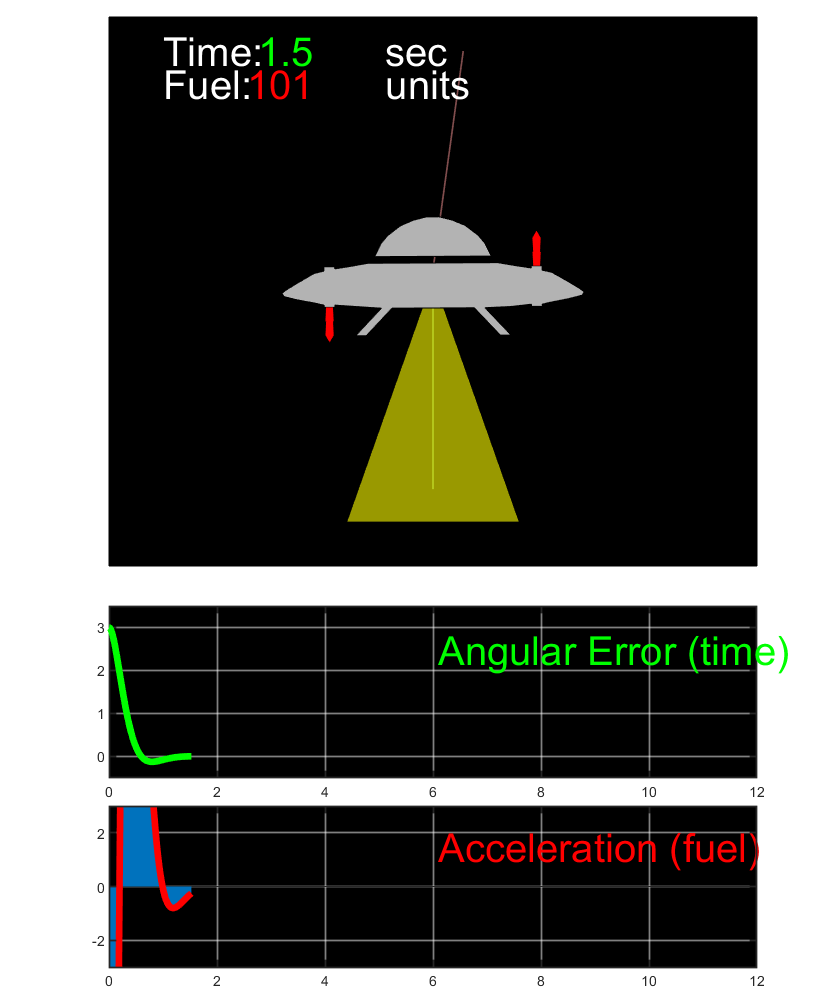


%% Create Animation

% Rotate to inital condition
ufo_rot = rot(ufo_data, x0(1));
r_thrust_rot = rot(thrust, x0(1));
l_thrust_rot = rot(thrust, x0(1));

% Set up the figure and the subplots
fig = figure('Position', [100 80 670 800]);
h3 = subplot(3, 1, 3);
h3.OuterPosition = [0 0.01 1 .19];
h3a = area(0, 0);
hold on
h3p = plot(0, 0, 'r');
h3.YGrid = 'on';
h3.XGrid = 'on';
h3.LineWidth = 1;
h3.Color = [0 0 0];
h3p.LineWidth = 4;
axis([0 12 -3 3]);
h3.GridColor = 'w';
h3.GridAlpha = 0.5;
text(6.1, 1.5, 'Acceleration (fuel)', 'Color', [1 0 0], 'FontSize', 24)

h2 = subplot(3, 1, 2);
h2.OuterPosition = [0 .2 1 .2];
h2p = plot(0, 0, 'g');
h2p.LineWidth = 4;
h2.YGrid = 'on';
h2.XGrid = 'on';
h2.LineWidth = 1;
h2.GridColor = 'w';
h2.GridAlpha = 0.5;
axis([0 12 -.5 3.5]);
h2.Color = [0 0 0];
text(6.1, 2.5, 'Angular Error (time)', 'Color', [0 1 0], 'FontSize', 24)

h1 = subplot(3, 1, 1);
h1.OuterPosition = [0 .4 1 0.63];
h1.XTick = [];
h1.YTick = [];
patch([-3 3 3 -3], [-1.7 -1.7 3.3 3.3], 'k');
axis([-3 3 -1.7 3.3]);
line([0 0.28], [1 2.99], 'Color', [0.5 0.3 0.3], 'LineWidth', 1);
line([0 0], [1 -1], 'Color', [0.3 0.5 0.3], 'LineWidth', 1);
H = patch(ufo_rot(:, 1), ufo_rot(:, 2) + yoffset, [0.7 0.7 0.7]);
RBT = patch(r_thrust_rot(:, 1), r_thrust_rot(:, 2), 'r');
LBT = patch(l_thrust_rot(:, 1), l_thrust_rot(:, 2), 'r');
RTT = patch(r_thrust_rot(:, 1), r_thrust_rot(:, 2), 'r');
LTT = patch(l_thrust_rot(:, 1), l_thrust_rot(:, 2), 'r');
RBT.FaceAlpha = 0;
LBT.FaceAlpha = 0;
RTT.FaceAlpha = 0;
LTT.FaceAlpha = 0;
RBT.EdgeColor = 'none';
LBT.EdgeColor = 'none';
RTT.EdgeColor = 'none';
LTT.EdgeColor = 'none';
hold on

% Initial time and fuel values
current_time = 0;
fuel = 0;

% Write time and fuel to the screen
text(-2.5, 3, 'Time:           sec', 'Color', [1 1 1], 'FontSize', 24,...
    'HorizontalAlignment', 'left');
text(-2.5, 2.7, 'Fuel:            units', 'Color', [1 1 1], 'FontSize', 24,...
    'HorizontalAlignment', 'left');

TME = text(-1.1, 3, num2str(current_time, '%.1f'), 'Color', [0 1 0], ...
'FontSize', 24, 'HorizontalAlignment', 'right');
FUL = text(-1.1, 2.7, num2str(fuel, '%.0f'), 'Color', [1 0 0], ...
'FontSize', 24, 'HorizontalAlignment', 'right');

accel_true = diff(x(:, 2))/(t(2)-t(1));

pause(2)

% Update Animation

for i = 1:5:length(x)-1
    
    % Simulation ending condition
    if and(abs(x(i,1)) < 0.011, abs(x(i,2)) < 0.011)
        x(i,1) = 0;
        pause(1);
        % Turn on tractor beam
        G = patch([0.1 0.8 -0.8 -0.1], [-0.35 -2.3 -2.3 -0.35] + yoffset, 'y');
        G.FaceAlpha = 0.6;
        return
    end
    
    % Scale acceleration to make thruster size look better fuel units
    % just a few digits (asthetics)
    accel_scaled = (x(i+1, 2) - x(i, 2));
    
    fuel = fuel + abs(accel_scaled);
    
    accel_scaled = min(2, max(-2, accel_scaled * 1000));
    
    % Scale thruster based on accleration and direction
    if accel_scaled > 0
        r_scaled(:, 1) = thrust(:, 1) * accel_scaled * 0.5;
        r_scaled(:, 2) = thrust(:, 2) * accel_scaled;
        l_scaled(:, 1) = thrust(:, 1);
        l_scaled(:, 2) = thrust(:, 2);
        
    elseif accel_scaled < 0
        r_scaled(:, 1) = thrust(:, 1);
        r_scaled(:, 2) = thrust(:, 2);
        l_scaled(:, 1) = thrust(:, 1) * -accel_scaled * 0.5;
        l_scaled(:, 2) = thrust(:, 2) * -accel_scaled;
    else
        r_scaled(:, 1) = thrust(:, 1);
        r_scaled(:, 2) = thrust(:, 2);
        l_scaled(:, 1) = thrust(:, 1);
        l_scaled(:, 2) = thrust(:, 2);
    end
    
    % Offset thrusters to place correctly on UFO
    rb_thrust = r_scaled + [0.96 -0.34];
    lb_thrust = l_scaled + [-0.96 -0.34];
    rt_thrust = l_scaled * [1 0; 0 -1] + [0.96, 0.03];
    lt_thrust = r_scaled * [1 0; 0 -1] + [-0.96, 0.03];
    
    % Rotate thrusters with UFO
    rb_thrust_rot = rot(rb_thrust, x(i,1)) + [0 yoffset];
    lb_thrust_rot = rot(lb_thrust, x(i,1)) + [0 yoffset];
    rt_thrust_rot = rot(rt_thrust, x(i,1)) + [0 yoffset];
    lt_thrust_rot = rot(lt_thrust, x(i,1)) + [0 yoffset];
    
    % Update thruster data 
    RBT.XData = rb_thrust_rot(:, 1);
    RBT.YData = rb_thrust_rot(:, 2);
    LBT.XData = lb_thrust_rot(:, 1);
    LBT.YData = lb_thrust_rot(:, 2);
    RTT.XData = rt_thrust_rot(:, 1);
    RTT.YData = rt_thrust_rot(:, 2);
    LTT.XData = lt_thrust_rot(:, 1);
    LTT.YData = lt_thrust_rot(:, 2);
    
   
    % Turn thrusters off if acceleration is low 
    if accel_scaled > 2e-1
        RBT.FaceAlpha = 1;
        LBT.FaceAlpha = 0;
        RTT.FaceAlpha = 0;
        LTT.FaceAlpha = 1;
        
    elseif accel_scaled < -2e-1
        RBT.FaceAlpha = 0;
        LBT.FaceAlpha = 1;
        RTT.FaceAlpha = 1;
        LTT.FaceAlpha = 0;
    else
        RBT.FaceAlpha = 0;
        LBT.FaceAlpha = 0;
        RTT.FaceAlpha = 0;
        LTT.FaceAlpha = 0;
    end
    
    % Rotate ufo
    ufo_rot = rot(ufo_data, x(i,1));
    H.XData = ufo_rot(:, 1);
    H.YData = ufo_rot(:, 2) + yoffset;
    h2p.XData = t(1:i);
    h2p.YData = x(1:i, 1);
    h3p.XData = t(1:i);
    h3p.YData = accel_true(1:i);
    h3a.XData = t(1:i);
    h3a.YData = accel_true(1:i);
    
    current_time = num2str(t(i), '%.1f');

    % Update time and fuel
    TME.String = current_time;
    FUL.String = num2str(fuel*30, '%.0f');
    
    pause(0.0001);
end

function output = rot(data, angle)
output = size(data);
Q = [cos(angle) -sin(angle); sin(angle) cos(angle)];
for i = 1:length(data)
    output(i, :) = Q * data(i, :)';
end
end